# Dynamical-System Initial-Condition Variation

Publication figure showing one closed-loop phase portrait and time series per saved test IC. The script loads saved test analyses only.

clear; clc; close all;
repo_root = project_root();
addpath(fullfile(repo_root, 'shared', 'matlab'), '-begin');
add_project_paths(repo_root);

## ---------------- Data Selection ----------------

Use the 32k primary network and network seed 1 for every system.

task_ids = {'dynamical_systems_lorenz', 'dynamical_systems_sprotts', ...
    'dynamical_systems_vanderpol'};
system_labels = {'Lorenz', 'Sprott S', 'Van der Pol'};
display_seed = 1;
required_n_hidden = 32000;
ic_indices = 1:5; % Each IC receives its own phase and time-series axes.

load_opts = struct();
load_opts.task_ids = string(task_ids);
load_opts.seed_indices = display_seed;
load_opts.required_n_hidden = required_n_hidden;
saved = load_saved_dynamics_test_results(load_opts);

## ---------------- Plot Controls ----------------

All time is measured after the 5-s closed-loop warmup used by the tests.

phase_tfrac = 1;
phase_stride = 5;
time_start_s = 20; % Post-warmup start time shown on the x-axis.
time_end_s = 30; % Post-warmup end time shown on the x-axis.
time_dimension = 1;
phase_x_limits_by_system = {[], [], []}; % One shared x-limit per system; [] derives it from that system.
phase_y_limits_by_system = {[], [], []}; % One shared y-limit per system; [] derives it from that system.
time_y_limits = []; % [] derives one shared limit across every time-series panel.

% Layout and typography
figure_position = [100 100 2100 1800];
left_margin = 0.10;
right_margin = 0.03;
bottom_margin = 0.06;
top_margin = 0.08;
horizontal_gap = 0.025;
vertical_gap = 0.055;
tick_font_size = 11;
label_font_size = 11;
title_font_size = 13;
panel_letter_font_size = 23;
panel_letters_enable = true;

% Standard dynamical-system colour convention.
network_color = [0 0 0];
true_color = [0.8660 0.3290 0.0000];
network_line_width = 0.8;
true_line_width = 0.8;
network_line_style = '-';
true_line_style = '-';

% Labels and titles
phase_x_label = 'x_1';
phase_y_label = 'x_2';
time_x_label = 'Time after warmup (s)';
time_y_label = 'x_1';
ic_title_prefix = 'Test IC ';

% Export controls
export_enable = false;
export_dir = fullfile(repo_root, 'shared', 'plotting', 'publication_figures', ...
    'generated_dynamics_ic_variation_figure');
export_file = 'dynamics_initial_condition_variation.png';
export_dpi = 500;

## ---------------- Build Figure ----------------

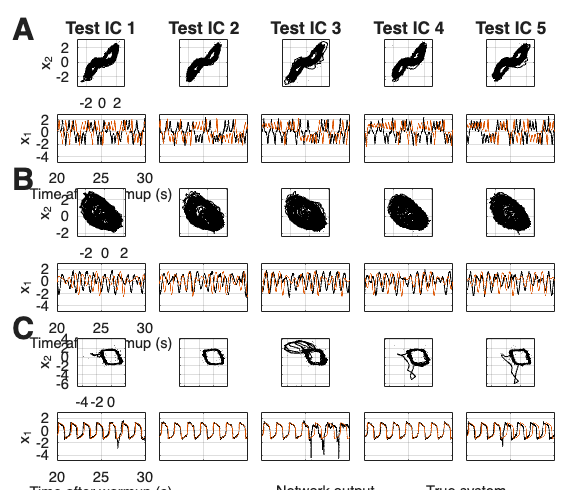

n_systems = numel(task_ids);
n_ics = numel(ic_indices);
data = repmat(struct('pred_by_ic', [], 'truth_by_ic', [], 'dt', []), 1, n_systems);
for ss = 1:n_systems
    entry = find_system_entry(saved.seed_results, task_ids{ss});
    [data(ss).pred_by_ic, data(ss).truth_by_ic, data(ss).dt] = closed_loop_trajectories(entry);
    validate_ics(ic_indices, numel(data(ss).pred_by_ic), system_labels{ss});
end
[phase_x_limits_by_system, phase_y_limits_by_system] = resolve_phase_limits(data, ic_indices, ...
    phase_tfrac, phase_stride, phase_x_limits_by_system, phase_y_limits_by_system);
time_y_limits = resolve_time_y_limits(data, ic_indices, time_dimension, time_start_s, time_end_s, time_y_limits);

fig = figure('Color', 'w', 'Position', figure_position);
positions = grid_positions(2*n_systems, n_ics, left_margin, right_margin, ...
    bottom_margin, top_margin, horizontal_gap, vertical_gap);
panel_letters = 'ABC';

for ss = 1:n_systems
    pred_by_ic = data(ss).pred_by_ic;
    truth_by_ic = data(ss).truth_by_ic;
    dt = data(ss).dt;
    phase_row = 2*ss - 1;
    time_row = 2*ss;
    phase_x_limits = phase_x_limits_by_system{ss};
    phase_y_limits = phase_y_limits_by_system{ss};

    for kk = 1:n_ics
        ic = ic_indices(kk);
        [pred, truth] = matched_trajectory(pred_by_ic{ic}, truth_by_ic{ic});

        phase_ax = axes(fig, 'Units', 'normalized', 'Position', positions{phase_row, kk});
        hold(phase_ax, 'on'); box(phase_ax, 'on'); grid(phase_ax, 'on'); axis(phase_ax, 'square');
        set_fixed_outer(phase_ax); phase_ax.FontSize = tick_font_size;
        idx = trajectory_indices(size(pred, 1), phase_tfrac, phase_stride);
        plot(phase_ax, pred(idx, 1), pred(idx, 2), network_line_style, 'Color', network_color, 'LineWidth', network_line_width);
        xlim(phase_ax, phase_x_limits); ylim(phase_ax, phase_y_limits);
        if phase_row == 1
            title(phase_ax, sprintf('%s%d', ic_title_prefix, ic), 'FontSize', title_font_size, 'FontWeight', 'bold');
        end
        if kk == 1
            ylabel(phase_ax, phase_y_label, 'FontSize', label_font_size);
            xlabel(phase_ax, phase_x_label, 'FontSize', label_font_size);
        else
            set(phase_ax, 'XTickLabel', [], 'YTickLabel', []);
        end

        time_ax = axes(fig, 'Units', 'normalized', 'Position', positions{time_row, kk});
        hold(time_ax, 'on'); box(time_ax, 'on'); grid(time_ax, 'on');
        set_fixed_outer(time_ax); time_ax.FontSize = tick_font_size;
        [time_idx, t] = time_interval_indices(size(pred, 1), dt, time_start_s, time_end_s);
        plot(time_ax, t, pred(time_idx, time_dimension), network_line_style, 'Color', network_color, 'LineWidth', network_line_width);
        plot(time_ax, t, truth(time_idx, time_dimension), true_line_style, 'Color', true_color, 'LineWidth', true_line_width);
        xlim(time_ax, [time_start_s time_end_s]); ylim(time_ax, time_y_limits);
        if kk == 1
            ylabel(time_ax, time_y_label, 'FontSize', label_font_size);
            xlabel(time_ax, time_x_label, 'FontSize', label_font_size);
        else
            set(time_ax, 'XTickLabel', [], 'YTickLabel', []);
        end
    end

    if panel_letters_enable
        add_panel_letter(fig, panel_letters(ss), positions{phase_row, 1}, panel_letter_font_size);
    end
end

add_style_legend(fig, [0.39 0.005 0.24 0.025], network_line_style, true_line_style, ...
    network_color, true_color, network_line_width, true_line_width, label_font_size);


if export_enable
    if exist(export_dir, 'dir') ~= 7, mkdir(export_dir); end
    print(fig, fullfile(export_dir, export_file), '-dpng', sprintf('-r%d', export_dpi));
end

## ---------------- Local Functions ----------------

function entry = find_system_entry(entries, task_id)
matches = find(arrayfun(@(x) strcmp(char(x.task_id), task_id), entries));
if numel(matches) ~= 1
    error('plot_dynamics_ic_variation_publication:systemSelection', ...
        'Expected one saved seed-1 entry for %s, found %d.', task_id, numel(matches));
end
entry = entries(matches);
end

function [pred_by_ic, truth_by_ic, dt] = closed_loop_trajectories(entry)
test = entry.test;
if isfield(test, 'closed_loop') && isstruct(test.closed_loop), test = test.closed_loop; end
if ~isfield(test, 'pred_norm_by_ic') || ~isfield(test, 'true_norm_by_ic')
    error('plot_dynamics_ic_variation_publication:missingTrajectories', ...
        '%s does not contain saved closed-loop trajectories by IC.', entry.task_id);
end
pred_by_ic = force_cell(test.pred_norm_by_ic);
truth_by_ic = force_cell(test.true_norm_by_ic);
dt = double(entry.options.dt);
if ~(isfinite(dt) && dt > 0), error('plot_dynamics_ic_variation_publication:invalidDt', 'Invalid saved dt.'); end
end

function cells = force_cell(value)
if ~iscell(value), cells = {value}; else, cells = value(:).'; end
end

function validate_ics(indices, n_available, system_label)
if any(indices < 1 | indices > n_available | indices ~= floor(indices))
    error('plot_dynamics_ic_variation_publication:invalidIC', ...
        '%s has %d saved test ICs; requested indices are [%s].', system_label, n_available, num2str(indices));
end
end

function [pred, truth] = matched_trajectory(pred, truth)
pred = double(pred); truth = double(truth);
n = min(size(pred, 1), size(truth, 1)); d = min(size(pred, 2), size(truth, 2));
if n < 2 || d < 2 || any(~isfinite(pred(1:n, 1:d)), 'all') || any(~isfinite(truth(1:n, 1:d)), 'all')
    error('plot_dynamics_ic_variation_publication:invalidTrajectory', 'Saved trajectory is not finite.');
end
pred = pred(1:n, 1:d); truth = truth(1:n, 1:d);
end

function idx = trajectory_indices(n, fraction, stride)
last = max(2, 1 + floor(max(eps, min(1, fraction)) * (n - 1)));
idx = 1:max(1, round(stride)):last;
end

function [idx, t] = time_interval_indices(n, dt, start_s, end_s)
if ~(isfinite(start_s) && isfinite(end_s) && start_s >= 0 && end_s > start_s)
    error('plot_dynamics_ic_variation_publication:invalidTimeWindow', ...
        'time_start_s must be nonnegative and time_end_s must exceed it.');
end
first = max(1, floor(start_s / dt) + 1);
last = min(n, floor(end_s / dt) + 1);
if last - first + 1 < 2
    error('plot_dynamics_ic_variation_publication:timeWindowOutsideTest', ...
        'The requested time interval [%.3g, %.3g] s is outside the saved test trajectory.', start_s, end_s);
end
idx = first:last;
t = (idx - 1).' * dt;
end

function [x_limits_by_system, y_limits_by_system] = resolve_phase_limits(data, ic_indices, fraction, stride, x_limits_by_system, y_limits_by_system)
if numel(x_limits_by_system) ~= numel(data) || numel(y_limits_by_system) ~= numel(data)
    error('plot_dynamics_ic_variation_publication:phaseLimits', ...
        'phase_x_limits_by_system and phase_y_limits_by_system must each have one entry per system.');
end
for ss = 1:numel(data)
    phase_values = [];
    for ic = ic_indices
        pred = double(data(ss).pred_by_ic{ic});
        idx = trajectory_indices(size(pred, 1), fraction, stride);
        phase_values = [phase_values; pred(idx, 1:2)]; %#ok<AGROW>
    end
    if isempty(x_limits_by_system{ss}), x_limits_by_system{ss} = padded_limits(phase_values(:, 1)); end
    if isempty(y_limits_by_system{ss}), y_limits_by_system{ss} = padded_limits(phase_values(:, 2)); end
end
end

function limits = resolve_time_y_limits(data, ic_indices, dimension, start_s, end_s, limits)
if ~isempty(limits), return; end
values = [];
for ss = 1:numel(data)
    for ic = ic_indices
        pred = double(data(ss).pred_by_ic{ic}); truth = double(data(ss).truth_by_ic{ic});
        [idx, ~] = time_interval_indices(min(size(pred, 1), size(truth, 1)), data(ss).dt, start_s, end_s);
        values = [values; pred(idx, dimension); truth(idx, dimension)]; %#ok<AGROW>
    end
end
limits = padded_limits(values);
end

function limits = padded_limits(values)
values = values(isfinite(values));
if isempty(values), limits = [-1 1]; return; end
span = max(max(values)-min(values), eps);
limits = [min(values)-.05*span max(values)+.05*span];
end

function positions = grid_positions(rows, cols, left, right, bottom, top, hgap, vgap)
positions = cell(rows, cols); width = (1-left-right-(cols-1)*hgap)/cols;
height = (1-top-bottom-(rows-1)*vgap)/rows;
for rr = 1:rows
    for cc = 1:cols
        positions{rr, cc} = [left+(cc-1)*(width+hgap), 1-top-rr*height-(rr-1)*vgap, width, height];
    end
end
end

function add_panel_letter(fig, letter, position, font_size)
annotation(fig, 'textbox', [.01 position(2)+position(4)+.005 .03 .03], ...
    'String', letter, 'FontSize', font_size, 'FontWeight', 'bold', ...
    'HorizontalAlignment', 'left', 'VerticalAlignment', 'middle', 'EdgeColor', 'none');
end

function add_style_legend(fig, position, network_style, true_style, network_color, true_color, network_width, true_width, font_size)
ax = axes(fig, 'Units', 'normalized', 'Position', position, 'Visible', 'off'); hold(ax, 'on');
h_network = plot(ax, NaN, NaN, network_style, 'Color', network_color, 'LineWidth', network_width);
h_true = plot(ax, NaN, NaN, true_style, 'Color', true_color, 'LineWidth', true_width);
legend(ax, [h_network h_true], {'Network output', 'True system'}, 'Box', 'off', ...
    'Orientation', 'horizontal', 'Location', 'southwest', 'FontSize', font_size);
end

function set_fixed_outer(ax)
if isprop(ax, 'ActivePositionProperty'), ax.ActivePositionProperty = 'Position'; end
if isprop(ax, 'PositionConstraint'), ax.PositionConstraint = 'innerposition'; end
end